%%%
% SPDX-License-Identifier: LGPL-3.0-or-later
% Copyright (c) 2025 Zherui Li
%%%

clearvars;

% addpath(genpath('./k-wave-toolbox-version-1.4'))
% addpath(genpath('./human skull models'))
% addpath(genpath('./transducer models'))

% ========================================================================= 
% DEFINE LITERALS 
% =========================================================================

% select which k-Wave code to run
%   1: MATLAB CPU code
%   2: MATLAB GPU code
%   3: C++ code
%   4: CUDA code
%   5: Save H5 file only
model           = 4;

% medium parameters
c0              = 1482;     % sound speed [m/s]
rho0            = 1000;     % density [kg/m^3]
alpha0          = 1/11.5128*3.48e-4; % water power law absorption coefficient [dB/(MHz^y cm)]

% skull parameters
c_skull         = 2850;     % skull sound speed, for human [m/s]
rho_skull       = 1732;     % skull density, for human [kg/m^3]
alpha_skull     = 1/11.5128*85; % human skull power law absorption coefficient [dB/(MHz^y cm)]

% source parameters
source_f0       = 7e5;      % source frequency [Hz]
source_diameter = 4e-3;     % disc diameter [m]
source_amp      = 1e6;      % source pressure [Pa]
focus_depth     = 35e-3;    % focus depth (ROC of the transducer) [m]

% grid parameters
axial_size      = 70e-3;    % total grid size in the axial dimension [m]
lateral_size    = 150e-3;   % total grid size in the lateral dimension [m]

% computational parameters
ppw             = 2;        % number of points per wavelength
t_end           = 50e-6;    % total compute time [s]
record_periods  = 1;        % number of periods to record
cfl             = 0.02;     % CFL number
source_x_offset = 20;       % grid points to offset the source
bli_tolerance   = 0.01;     % tolerance for truncation of the off-grid source points
upsampling_rate = 10;       % density of integration points relative to grid

% ========================================================================= 
% DEFINE KGRID 
% =========================================================================

% calculate the grid spacing based on the PPW and F0
dx = c0 / (ppw * source_f0);   % [m]

% compute the size of the grid
Nx = roundEven(axial_size / dx) + source_x_offset;
Ny = roundEven(lateral_size / dx);
Nz = Ny;

% create the computational grid
kgrid = kWaveGrid(Nx, dx, Ny, dx, Nz, dx);

% compute points per temporal period
PPP = round(ppw / cfl);

% compute corresponding time spacing
dt = 1 / (PPP * source_f0);

% create the time array using an integer number of points per period
Nt = round(t_end / dt);
kgrid.setTime(Nt, dt);

% calculate the actual CFL and PPW
disp(['PPW = ' num2str(c0 / (dx * source_f0))]);

PPW = 2


disp(['CFL = ' num2str(c0 * dt / dx)]);

CFL = 0.02


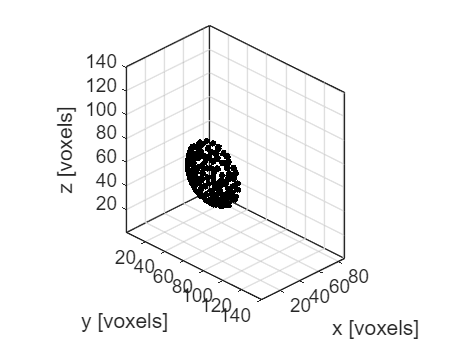

% ========================================================================= 
% DEFINE KWAVEARRAY FOR TRANDUCER 
% =========================================================================

% load H-275 element sptial positions
pos = load('H275_elementsPos_Sorted.mat');
pos = getfield(pos, 'H275_ElementPos_sorted'); % #, X, Y, Z
pos(:,[2 4]) = pos(:,[4 2]); % #, Z, Y, X
pos(:,[3 4]) = pos(:,[4 3]); % #, Z, X, Y

% set element position
elem_pos = pos(:,2:4) * 1e-3;
elem_pos(:,1) = elem_pos(:,1) + abs(min(gather(elem_pos(:,1)))) + ... % let all x>=0
    kgrid.x_vec(1) + (source_x_offset-15) * kgrid.dx;

% set element focus position
focus_pos = [min(gather(elem_pos(:,1))) + focus_depth, 0, 0];

% create empty kWaveArray
karray = kWaveArray('BLITolerance', bli_tolerance, 'UpsamplingRate', upsampling_rate, 'SinglePrecision', true);

% add disc shaped elements
for i = 1:size(elem_pos,1)
    karray.addDiscElement(elem_pos(i,:), source_diameter, focus_pos);
end

% (optional) visualize transducer element arrrangements
grid_weights = karray.getArrayGridWeights(kgrid);
grid_weights_bin = imbinarize(grid_weights);
clear grid_weights;

figure
voxelPlot(single(grid_weights_bin));

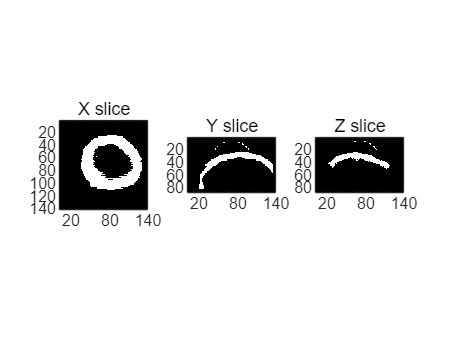

% ========================================================================= 
% DEFINE BINARY SKULL/BRAIN MASK 
% =========================================================================

% load skull model from pCT
skull_bone = niftiread('./H-275 3D Simulations/subjects/tFUS47/tFUS47_pct.nii');
skull_bone = skull_bone > 140; % set threshold for binary mask

% calculate the scale factor to achieve current dx
scale_factor = 1 / (dx*1e3);

% resample the skull model to have the new voxel size
skull_bone = imresize3(skull_bone, scale_factor, 'nearest');

% cut skull bone
skull_bone(88:end, :, :) = 0;
skull_bone(:, 100:end, :) = 0;
skull_bone(:, :, 1:70) = 0;

% set valid range
skull_bone = skull_bone(12:80, :, :); % x-axis
skull_bone = skull_bone(:, 19:92, :);  % y-axis
skull_bone = skull_bone(:, :, 75:215); % z-axis

% rotation
skull_bone = imrotate3(double(skull_bone), -90, [0 0 1], 'nearest');
skull_bone = imrotate3(double(skull_bone), 45, [0 0 1], 'nearest');

% create a binary mask for the skull
skull_mask = zeros(Nx, Ny, Nz, 'logical');
skull_mask(ceil(Nx/2)-ceil(size(skull_bone,1)/2)+28:ceil(Nx/2)+ceil(size(skull_bone,1)/2)-42+28, ...
    ceil(Ny/2)-ceil(size(skull_bone,2)/2)+1:ceil(Ny/2)+ceil(size(skull_bone,2)/2)-1+1, ...
    ceil(Nz/2)-ceil(size(skull_bone,3)/2)+19:ceil(Nz/2)+ceil(size(skull_bone,3)/2)-24+19) = skull_bone(30:90,:,1:end-22);

% (optional) visualize transducer elements and skull
transducer_all_mask = or(skull_mask,grid_weights_bin);

figure
subplot(1,3,1), imagesc(squeeze(transducer_all_mask(ceil(end/2)-5,:,:))); title('X slice'); axis image; colormap gray;
subplot(1,3,2), imagesc(squeeze(transducer_all_mask(:,ceil(end/2),:))); title('Y slice'); axis image; colormap gray;
subplot(1,3,3), imagesc(squeeze(transducer_all_mask(:,:,ceil(end/2)))); title('Z slice'); axis image; colormap gray;

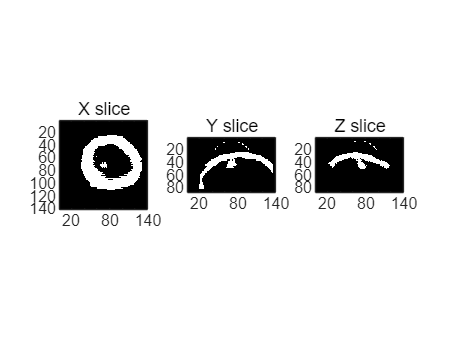

% import brain region MRI
V5_mask = niftiread('./H-275 3D Simulations/subjects/tFUS47/tFUS47_V5_L_native.nii.gz');
V5_mask = V5_mask > 0; % set threshold for binary mask

% calculate the scale factor to achieve current dx
scale_factor = 1 / (dx*1e3);

% resample the V5 mask to have the new voxel size
V5_mask = imresize3(V5_mask, scale_factor, 'nearest');

% set valid range
V5_mask = V5_mask(12:80, :, :); % x-axis
V5_mask = V5_mask(:, 19:92, :);  % y-axis
V5_mask = V5_mask(:, :, 75:215); % z-axis

% rotation
V5_mask = imrotate3(double(V5_mask), -90, [0 0 1], 'nearest');
V5_mask = imrotate3(double(V5_mask), 45, [0 0 1], 'nearest');

% create a binary mask for V5
brain_mask = zeros(Nx, Ny, Nz, 'logical');
brain_mask(ceil(Nx/2)-ceil(size(V5_mask,1)/2)+28:ceil(Nx/2)+ceil(size(V5_mask,1)/2)-42+28, ...
    ceil(Ny/2)-ceil(size(V5_mask,2)/2)+1:ceil(Ny/2)+ceil(size(V5_mask,2)/2)-1+1, ...
    ceil(Nz/2)-ceil(size(V5_mask,3)/2)+19:ceil(Nz/2)+ceil(size(V5_mask,3)/2)-24+19) = V5_mask(30:90,:,1:end-22);

% (optional) visualize transducer elements, skull, and the brain
brain_all_mask = or(brain_mask,transducer_all_mask);

figure
subplot(1,3,1), imagesc(squeeze(brain_all_mask(ceil(end/2)-5,:,:))); title('X slice'); axis image; colormap gray;
subplot(1,3,2), imagesc(squeeze(brain_all_mask(:,ceil(end/2),:))); title('Y slice'); axis image; colormap gray;
subplot(1,3,3), imagesc(squeeze(brain_all_mask(:,:,ceil(end/2)))); title('Z slice'); axis image; colormap gray;

% ========================================================================= 
% DEFINE SOURCE SIGNAL 
% =========================================================================

%%% create time varying source (without corr)
% source_sig = createCWSignals(kgrid.t_array, source_f0, source_amp, 0);
% source_sig_all = repmat(source_sig, size(elem_pos,1), 1);

%%% create time varying source (with corr)
filename = './H-275 3D Simulations/subjects/tFUS47/tFUS47_phase_delay_v5.xlsx';
Kranion_ACT_filename = './H-275 3D Simulations/subjects/tFUS47/tFUS47_ACT.txt';

phase_delay = readmatrix(filename, 'Range','C2:C129');
time_step_diff = readmatrix(filename, 'Range','B2:B129');
Kranion_ACT = readtable(Kranion_ACT_filename);

source_sig_all = zeros(size(elem_pos,1), size(kgrid.t_array,2));
for i=1:size(elem_pos,1)
    % try our estimated data (kPR)
    % WITHOUT activating channels with extremely large delay/no peaks found
    if abs(time_step_diff(i)) < 100 & phase_delay(i) ~= -1 & time_step_diff(i) ~= -1 % 100 is the wave period in [time pts]
        % take positive value of phase_delay [rad] for phase correction
        source_sig_all(i,:) = createCWSignals(kgrid.t_array, source_f0, source_amp, phase_delay(i));
    end

    % try Kranion data (for active channel selection only, KE)
    % if Kranion_ACT{i, 3} == 1
    %     source_sig_all(i,:) = createCWSignals(kgrid.t_array, source_f0, source_amp, phase_delay(i));
    % end

    % try Kranion data (for phase delay and channel selection, KE+Ph)
    % if Kranion_ACT{i, 3} == 1
    %     source_sig_all(i,:) = createCWSignals(kgrid.t_array, source_f0, source_amp, -Kranion_ACT{i, 4});
    % end
end

% assign binary mask
source.p_mask = karray.getArrayBinaryMask(kgrid);

% assign source signals
source.p = karray.getDistributedSourceSignal(kgrid, source_sig_all);

Computing distributed source signal...
  calculating binary mask...                  completed in 3.012s
  approximate size of source matrix:          6.2 GB (single precision)
  total computation time 58.016s


% ========================================================================= 
% DEFINE MEDIUM 
% =========================================================================

% assign medium properties
medium.sound_speed = c0.*ones(Nx, Ny, Nz);
medium.sound_speed(skull_mask) = c_skull;

medium.density = rho0.*ones(Nx, Ny, Nz);
medium.density(skull_mask) = rho_skull;

medium.alpha_coeff = alpha0.*ones(Nx, Ny, Nz);
medium.alpha_coeff(skull_mask) = alpha_skull;

medium.alpha_power = 1.001;

% ========================================================================= 
% DEFINE SENSOR 
% =========================================================================

% set sensor mask
sensor.mask = zeros(Nx, Ny, Nz);
sensor.mask(source_x_offset + 2:end, :, :) = 1;

% record the pressure
sensor.record = {'p'};

% record all periods
sensor.record_start_index = 1;

% (optional) record only the final few periods when the field is in steady state
% sensor.record_start_index = kgrid.Nt - record_periods * 10 * PPP + 1;

% ========================================================================= 
% SIMULATION 
% =========================================================================

% set input options
input_args = {...
    'PMLSize', 'auto', ...
    'PMLInside', false, ...
    'PlotPML', false, ...
    'DisplayMask', 'off', ...
    'PlotSim', false};

% run code
switch model
    case 1
        
        % MATLAB CPU
        sensor_data = kspaceFirstOrder3D(kgrid, medium, source, sensor, ...
            input_args{:}, ...
            'DataCast', 'single', ...
            'PlotScale', [-1, 1] * source_amp);
        
    case 2
        
        % MATLAB GPU
        sensor_data = kspaceFirstOrder3D(kgrid, medium, source, sensor, ...
            input_args{:}, ...
            'DataCast', 'gpuArray-single', ...
            'PlotScale', [-1, 1] * source_amp);
     
    case 3
        
        % C++
        sensor_data = kspaceFirstOrder3DC(kgrid, medium, source, sensor, input_args{:});
        
    case 4
        
        % C++/CUDA GPU
        sensor_data = kspaceFirstOrder3DG(kgrid, medium, source, sensor, input_args{:});
        
    case 5

        % Save H5 file only
        filename = './test_input.h5';
        sensor_data = kspaceFirstOrder3D(kgrid, medium, source, sensor, ...
            'SaveToDisk', filename);
end

Running k-Wave simulation...
  start time: 04-Apr-2025 17:42:20
  reference sound speed: 2850m/s
  dt: 14.2857ns, t_end: 49.9857us, time steps: 3500
  input grid size: 86 by 140 by 140 grid points (92.1429 by 150 by 150mm)
  maximum supported frequency: 700kHz
  expanding computational grid...
  computational grid size: 128 by 162 by 162 grid points
  precomputation completed in 21.2817s
  saving input files to disk...
  completed in 5.9713s
+---------------------------------------------------------------+ 
|                  kspaceFirstOrder-CUDA v1.3                   | 
+---------------------------------------------------------------+ 
| Reading simulation configuration:                        Done | 
| Selected GPU device id:                                     0 | 
| GPU device name:                      NVIDIA GeForce RTX 5090 | 
| Number of CPU threads:                                      1 | 
| Processor name:          13th Gen Intel(R) Core(TM) i9-13900K | 
+-----------------

% extract amplitude from the sensor data
amp = extractAmpPhase(sensor_data.p, 1/kgrid.dt, source_f0, ...
    'Dim', 2, 'Window', 'Rectangular', 'FFTPadding', 1);

% reshape data
amp = reshape(amp, Nx - source_x_offset - 1, Ny, []);

% extract pressure on axis
amp_on_axis = squeeze(amp(:, :, Nz/2 + 1));
amp_on_axis = amp_on_axis(:, Ny/2 + 1);

% define axis vectors for plotting
x_vec = kgrid.x_vec(source_x_offset + 2:end, :) - kgrid.x_vec(source_x_offset + 1);
y_vec = kgrid.y_vec;
z_vec = kgrid.z_vec;

Focus Location (x, y, z): (20.357143 mm, 0.000000 mm, 0.000000 mm)
Axial Diameter (x): 10.714286 mm
Lateral Diameter (y): 2.142857 mm
Lateral Diameter (z): 3.214286 mm
Focal Volume: 60.267857 mm^3
Avg Pressure within Focus: 328.055695 kPa

Overlap Volume with Brain Mask: 60.267857 mm^3
Overlap Rate with Brain Mask: 2.657267 %
Average Pressure within Brain Mask: 328.055695 kPa

Energy Delivered to Overlapping Region: 2.594360e+00 mJ

Peak Pressure Location (x, y, z): (18.214286 mm, 0.000000 mm, 0.000000 mm)
The peak pressure is within the brain region.


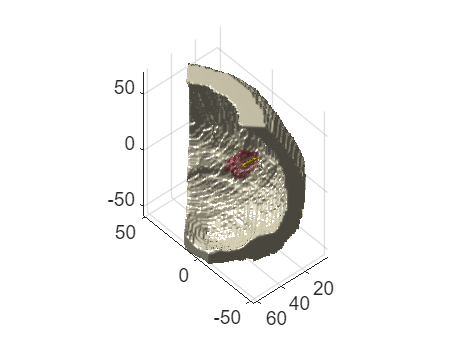

% ========================================================================= 
% EVALUATION 
% =========================================================================

brain_mask_s = brain_mask(source_x_offset + 2:end, :, :);
skull_mask_s = skull_mask(source_x_offset + 2:end, :, :);

FocusEva3D(amp,kgrid.dx,kgrid.dy,kgrid.dz,x_vec,y_vec,z_vec,skull_mask_s,brain_mask_s);

function FocusEva3D(amp_tmp, dx, dy, dz, x_vec, y_vec, z_vec, skull_mask, brain_mask)
    % restrict the search range and apply skull_mask to amp_tmp
    amp_tmp(1:10, :, :) = 0;  % Eliminate focus at x <= 15
    amp_tmp(:, 1:66, :) = 0;  % Eliminate focus at y <= 67
    amp_tmp(:, 76:end, :) = 0;  % Eliminate focus at y >= 74
    amp_tmp(:, :, 1:66) = 0;  % Eliminate focus at z <= 52
    amp_tmp(:, :, 76:end) = 0;  % Eliminate focus at z >= 76
    amp_tmp(skull_mask) = 0;  % Eliminate areas inside skull mask

    % handle gpuArray type: move data to CPU if necessary for bwconncomp
    is_gpu = isa(amp_tmp, 'gpuArray');
    if is_gpu
        amp_tmp_cpu = gather(amp_tmp);
    else
        amp_tmp_cpu = amp_tmp;
    end

    % find the maximum pressure (focus point) in the 3D matrix
    [max_pressure, max_idx] = max(amp_tmp_cpu(:)); 

    % define threshold for the focal region at -6 dB (FWHM)
    pressure_threshold = max_pressure / 2;

    % create a 3D binary mask for the focal region within the -6 dB threshold
    focal_region_cpu = amp_tmp_cpu >= pressure_threshold;

    % perform connected component analysis on the CPU
    cc = bwconncomp(focal_region_cpu, 6);  % 6-connectivity for 3D data

    % find the largest connected component
    numPixels = cellfun(@numel, cc.PixelIdxList);
    [~, idxLargest] = max(numPixels);
    largest_focal_region_cpu = false(size(focal_region_cpu));
    largest_focal_region_cpu(cc.PixelIdxList{idxLargest}) = true;  % keep only the largest component

    % move data back to GPU if the input was a gpuArray
    if is_gpu
        largest_focal_region = gpuArray(largest_focal_region_cpu);
    else
        largest_focal_region = largest_focal_region_cpu;
    end

    % calculate the centroid of the largest connected focal region
    [x_focus, y_focus, z_focus] = ind2sub(size(largest_focal_region), find(largest_focal_region));
    focus_x = x_vec(round(mean(x_focus)));
    focus_y = y_vec(round(mean(y_focus)));
    focus_z = z_vec(round(mean(z_focus)));

    % calculte the peak position
    [max_x_idx, max_y_idx, max_z_idx] = ind2sub(size(amp_tmp_cpu), max_idx);
    peak_x = x_vec(max_x_idx);
    peak_y = y_vec(max_y_idx);
    peak_z = z_vec(max_z_idx);

    % check if the peak position is within the brain region
    is_peak_in_brain = brain_mask(max_x_idx, max_y_idx, max_z_idx);

    % calculate the focal volume by summing all voxels within the largest connected focal region
    voxel_volume = dx * dy * dz;
    focal_volume = sum(largest_focal_region(:)) * voxel_volume;

    % calculate the average acoustic pressure within the largest connected focal region
    acoustic_pressure_focus = mean(amp_tmp(largest_focal_region));

    % calculate the average pressure within the brain mask area
    brain_area_pressure = amp_tmp(and(brain_mask,largest_focal_region));
    avg_brain_pressure = mean(brain_area_pressure(brain_area_pressure ~= 0));

    % calculate the axial and lateral diameters of the focus
    axial_diameter = (max(x_focus) - min(x_focus)) * dx;    % x-axis
    lateral_diameter = (max(y_focus) - min(y_focus)) * dy;  % y-axis
    depth_diameter = (max(z_focus) - min(z_focus)) * dz;    % z-axis

    % display the results
    fprintf('Focus Location (x, y, z): (%f mm, %f mm, %f mm)\n', focus_x * 1e3, focus_y * 1e3, focus_z * 1e3);
    fprintf('Axial Diameter (x): %f mm\n', axial_diameter * 1e3);
    fprintf('Lateral Diameter (y): %f mm\n', lateral_diameter * 1e3);
    fprintf('Lateral Diameter (z): %f mm\n', depth_diameter * 1e3);
    fprintf('Focal Volume: %f mm^3\n', focal_volume * 1e9);  % in [mm^3]
    fprintf('Avg Pressure within Focus: %f kPa\n', acoustic_pressure_focus * 1e-3);

    % calculate overlap rate between the brain mask and focus region
    brain_focus_overlap = brain_mask & largest_focal_region;
    overlap_voxels = sum(brain_focus_overlap(:));
    total_brain_voxels = sum(brain_mask(:));
    overlap_rate = overlap_voxels / total_brain_voxels;
    overlap_volume = overlap_voxels * voxel_volume;
    % display the result
    fprintf('\nOverlap Volume with Brain Mask: %f mm^3\n', overlap_volume * 1e9);  % in [mm^3]
    fprintf('Overlap Rate with Brain Mask: %f %%\n', overlap_rate * 100);
    fprintf('Average Pressure within Brain Mask: %f kPa\n', avg_brain_pressure * 1e-3);

    % define constants for 'brain' tissue (use water here)
    rho = 1000;  % density [kg/m^3]
    c = 1482;    % speed of sound [m/s]
    % calculate acoustic energy density in the overlapping region
    energy_density = (avg_brain_pressure)^2 / (rho * c^2);
    % calculate the total energy delivered to the overlapping region
    energy_delivered = energy_density * overlap_volume;
    % display the result
    fprintf('\nEnergy Delivered to Overlapping Region: %e mJ\n', energy_delivered * 1e6);

    % display the peak pressure location and status
    fprintf('\nPeak Pressure Location (x, y, z): (%f mm, %f mm, %f mm)\n', peak_x * 1e3, peak_y * 1e3, peak_z * 1e3);
    if is_peak_in_brain
        fprintf('The peak pressure is within the brain region.\n');
    else
        fprintf('The peak pressure is NOT within the brain region.\n');
    end

    % generate 3D grids for x, y, z
    [X, Y, Z] = meshgrid(y_vec*1e3, x_vec*1e3, z_vec*1e3);

    % display 3D volume of the focus using isosurface
    figure
    fv = isosurface(X, Y, Z, amp_tmp_cpu, pressure_threshold);
    p1 = patch(fv);
    isonormals(X, Y, Z, amp_tmp_cpu, p1);
    set(p1, 'FaceColor', [0.4660 0.6740 0.1880], 'EdgeColor', 'none', 'FaceAlpha', 1);  % set focal region to green
    % set(p1, 'FaceColor', [1 1 0], 'EdgeColor', 'none', 'FaceAlpha', 1);  % set focal region to yellow
    hold on
    
    % plot the skull mask
    p2 = patch(isosurface(X, Y, Z, skull_mask, 0.5));
    isonormals(X, Y, Z, skull_mask, p2);
    set(p2, 'FaceColor', [0.95, 0.92, 0.8], 'EdgeColor', 'none', 'FaceAlpha', 1);
    
    % plot the brain mask
    p3 = patch(isosurface(X, Y, Z, brain_mask, 0.5));
    isonormals(X, Y, Z, brain_mask, p3);
    set(p3, 'FaceColor', [0.6350 0.0780 0.1840], 'EdgeColor', 'none', 'FaceAlpha', 0.3);

    % apply lighting
    camlight;
    lighting gouraud;
    
    axis tight;
    daspect([1 1 1]);    % ensure equal scaling of axes
    view(-37.5*3.5,45);  % set a fixed view angle
    grid on;
    hold off;
end